load Hmatrix3.mat
p=0:0.1:1;
Nsim=1000;
colm = size(H,2)

colm = 12

row = size(H,1)

row = 9

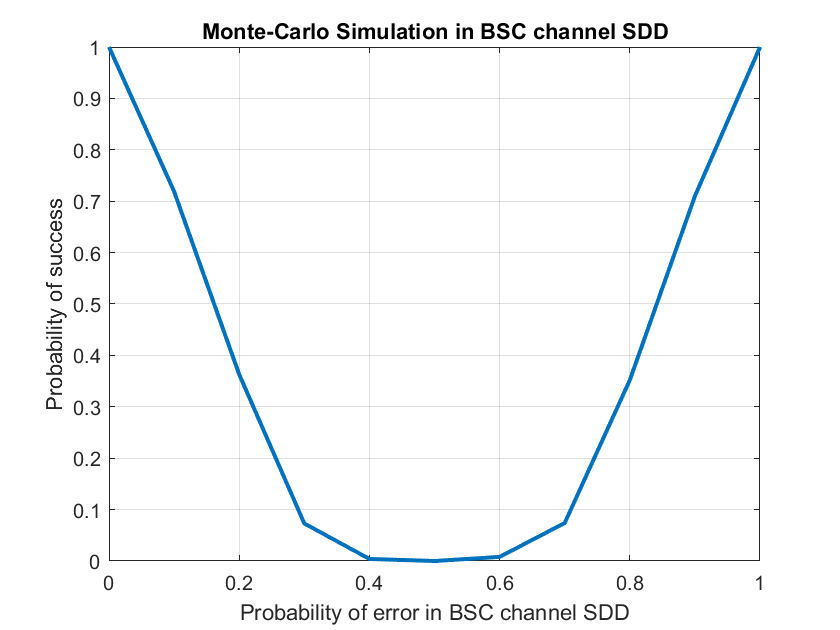


Lj_prev=zeros(1,colm); %For Breaking Condition
transmitted=zeros(1,colm); %Input of BSC Channel 
nsuc=zeros(1,length(p));   %Array to store success
cnt=1; 
for a=p
    for b=1:Nsim %Monte-Carlo Simulation
        noise=rand(1,colm)<a; %noise generated
        Msg_received1=xor(transmitted,noise); % Message generating 
        llr=zeros(1,colm); %log likelihood ratio
        
        %Loading The Message from VN to CN
        for i=1:colm %loading log likelihood ratio of MSG
            if Msg_received1(i)==1
                llr(i)=log(a/(1-a));
            else
                llr(i)=log((1-a)/a); % Log of odd in favor of zero
            end
        end
        
        Mji1=zeros(row,colm); %LLR Ratio's VN to CN
        for i=1:row
            for j=1:colm
                if H(i,j)==1 %storing LLR of VN connected to CN in matrix
                    Mji1(i,j)=llr(j); %for first iteration
                end
            end
        end
        
        Eij=zeros(row,colm); % CN calculation
        for i=1:row
            for j=1:colm
                if Mji1(i,j)~=0 %checking whether there is any value of LLR present in matrix
                    temp_cnt=1;
                    not_ii=j;
                    for ii=1:colm 
                        if (ii~=not_ii) && (Mji1(i,ii)~=0)  
                            temp_Mji=Mji1(i,ii);
                            %tanh(1/2*log(1-p/p))=1-2p
                            temp_cnt=temp_cnt * tanh(temp_Mji/2); %Probabilities passing from VN to CN
                        end
                    end         
                    Eij(i,j)=log((1+temp_cnt)/(1-temp_cnt)); % Loading LLR of all mulitplied probabilites 
                    %LLR of CN thinks that VN is 0 / CN thinks that VN is 1
                end
            end
        end
        
        Li=zeros(1,colm); %Decision Boundary 
        for i=1:colm
            onlylj=sum(Eij(:,i))+llr(i); %Adding llr of all the CN->VN and llr from channel
            Li(i)=onlylj; 
        end
        
        Msg_received2=zeros(1,colm);
        for i=1:colm
            if Li(i)<=0
                Msg_received2(i)=1;
            end
        end
        
        if(sum(Msg_received2)==0) %If decoded message is all zeros 
            nsuc(cnt)=nsuc(cnt)+1;
        else
            for iit=1:50
                Mji2=zeros(row,colm);
                for i=1:row
                    for j=1:colm
                        if H(i,j)==1
                            temp_cnt=0;
                            not_ii=i;
                            for ii=1:row
                                if (Eij(ii,j)~=0) && (ii~=not_ii)
                                    temp_cnt=temp_cnt+Eij(ii,j);
                                end
                            end                          
                            Mji2(i,j)=temp_cnt+llr(j);
                        end
                    end
                end
                
                Eij=zeros(row,colm);
                for i=1:row
                    for j=1:colm
                        if Mji2(i,j)~=0
                            temp_cnt=1;
                            not_ii=j;
                            for ii=1:colm
                                if (ii~=not_ii) && (Mji2(i,ii)~=0)
                                    temp_Mji=Mji2(i,ii);
                                    temp_cnt=temp_cnt * tanh(temp_Mji/2);
                                end
                            end                           
                            Eij(i,j)=log((1+temp_cnt)/(1-temp_cnt)); 
                        end
                    end
                end
                
                Li=zeros(1,colm);
                for i=1:colm
                    onlylj=sum(Eij(:,i))+llr(i);                  
                    Li(i)=onlylj;
                end
           
                if(Li==Lj_prev) %If LLR does not change after iteration
                    %It means that no further decoding is possible
                    if(iit~=1) %This code can't be decoded
                        break;
                    end
                end
                Lj_prev=Li;

                Msg_received2=zeros(1,colm);
                for i=1:colm
                    if Li(i)<=0
                        Msg_received2(i)=1;
                    end
                end
                
                if(sum(Msg_received2)==0) % Successfully decoded
                    nsuc(cnt)=nsuc(cnt)+1; %incrementing the counter
                    break;
                end
            end
        end
    end
    cnt=cnt+1;
end

plot(p,nsuc/Nsim,"LineWidth",2);
grid on;
title("Monte-Carlo Simulation in BSC channel SDD");
xlabel("Probability of error in BSC channel SDD");ylabel("Probability of success"); grid on;